## Linear Algebra Concepts

### Rank

The `rank(A)` function calculates the rank of matrix `A`, which represents the dimension of the column space of `A`. The rank tells us how many linearly independent vectors span the column space.

% Define Matrix
A = [1 1 2; -1 1 0; 2 1 3];
% Compute the Rank
rank(A)

ans = 2

## Vector Transformation

Matrix-vector multiplication can be visualized as a transformation. When you multiply a vector by a matrix, you transform the vector to a new location in the space defined by the matrix.

### Vectors 3D Space 

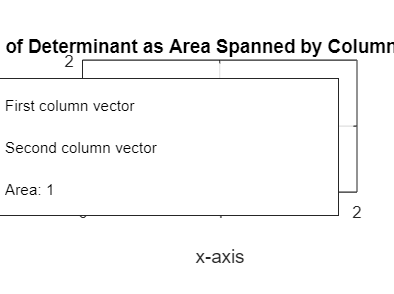

x = randn(3,1000);
figure 
plot3(x(1,:),x(2,:),x(3,:),'.');
title("Vectors in 3-dimensional space");

### Vectors in 3D Space Transformed

The follwing code visually showcases how a set of 3D vectors (from matrix `x`) gets transformed when multiplied by the matrix `A`. The transformation may involve rotations, stretches, or compressions depending on the values in matrix `A`.

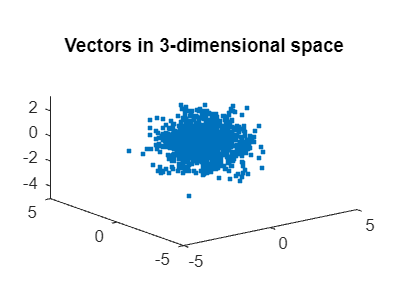

A = [1 1 2; -1 1 0; 2 1 3];

% Transform the set of 3D vectors using matrix A
Y = A*x;

% Create a 3D scatter plot for the transformed vectors
figure; % Open a new figure
plot3(Y(1,:),Y(2,:),Y(3,:),'.')
hold on; 

title("Vector Transformation Y=Ax")
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

### Visualizing Matrix Transformations and Basis Vectors in 3D

The code demonstrates how the matrix *A* acts as a linear transformation on input vectors, transforming them into new positions in the 3D space.

 Additionally, by plotting the column vectors of *A* (a1, a2, and a3) as red lines, it visually highlights these vectors as the basis vectors for the transformation. 

These basis vectors give insight into the "**directions**" and "**scales**" of the transformation applied by *A* in the 3D space. 

The longer the red line in a certain direction, the stronger the influence of that basis vector in that direction.

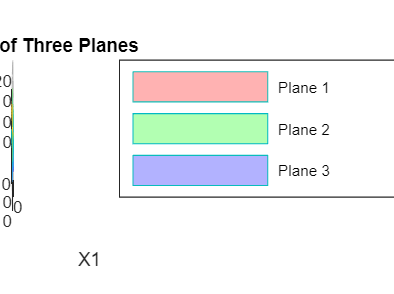

% Transform the set of 3D vectors using matrix A
Y = A*x;

% Create a 3D scatter plot for the transformed vectors
figure; % Open a new figure
plot3(Y(1,:),Y(2,:),Y(3,:),'.')
hold on; 

% Extract the column vectors of matrix A
a1 = A(:, 1); % First column of A
a2 = A(:, 2); % Second column of A
a3 = A(:,3);  % Third column of A

% Visualize the column vectors of A on the same plot
plot3([0 a1(1)], [0 a1(2)], [0 a1(3)], 'r', 'linewidth', 4) % a1 in red
plot3([0 a2(1)], [0 a2(2)], [0 a2(3)], 'r', 'linewidth', 4) % a2 in red
plot3([0 a3(1)], [0 a3(2)], [0 a3(3)], 'r', 'linewidth', 4) % a3 in red

% Add title and labels to the plot
title("3D Vector Transformation and Basis Vectors of A")
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

### Visualizing Column Vectors

In this section we just plot column vectors of a matrix and visualize it 

% Define matrix A with 3 rows and 4 columns
A = [1 2 3 4; -1 1 -1 1; 0 1 -3 0];
rank(A)

ans = 3


% Create a new figure window for plotting
figure 

% Create an empty cell array to store legend entries
legendEntries = cell(1, 4);

% Loop through each column of matrix A
for i = 1:4
    % Plot the column vector of A as a line segment in 3D space
    % starting from the origin (0,0,0) and ending at the point defined by the column vector
    plot3([0 A(1,i)], [0 A(2,i)], [0 A(3,i)], 'linewidth', 4);
    hold on; % Keep the current plot and add subsequent plots on top
    
    % Add the column index to the legend entries
    legendEntries{i} = ['Column ' num2str(i)];
end

% Add the legend to the plot
legend(legendEntries);

% Set the title for the plot
title('Visualization of Column Vectors of Matrix A');

### Geometric Interpretation of Determinants

For a 2x2 matrix the area of the parallelogram formed by the columns (or rows) of A

For a 3x3 matrix it represents the volume of a parallelopiped formed by the columns (or rows) of A

This concept can be extended to any dimensional matrix

% Define the matrix A
A = [0 1; 1 0];

% Extract the column vectors
vec1 = A(:,1);
vec2 = A(:,2);

% Create a new figure
figure

% Plot the first vector in red
quiver(0,0,vec1(1),vec1(2),"r","LineWidth",2,"MaxHeadSize",0.5)
hold on 

% Plot the second vector in blue
quiver(0,0,vec2(1),vec2(2),"b","LineWidth",2,"MaxHeadSize",0.5)

% Set the limits of the plot
xlim([0 2]);
ylim([0 2]);

% Turn on the grid
grid on;


% Label the axes
xlabel('x-axis');
ylabel('y-axis');


% Fill the area formed by vec1 and vec2 with a semi-transparent cyan color
fill([0 vec1(1) vec1(1)+vec2(1) vec2(1)],[0 vec1(2) vec1(2)+vec2(2) vec2(2)], 'c', 'FaceAlpha', 0.3)

% Add a legend and title
legend('First column vector', 'Second column vector', ['Area: ', num2str(abs(det(A)))]);
title('Demonstration of Determinant as Area Spanned by Column Vectors of Matrix A');

## Visualizing System Of Equations and their Solutions

In linear algebra, a system of equations can be represented visually using planes in a three dimensional space. 

The following matrix A and the vector b defines our system of equations. Each equation represents a plan in 3D space. 

The way the planes interact will tell provide insight on the solution of the system

- If the planes intersect at a single point, the system has a unique solution

- If they intersect along a line, the system has infinite solutions

- If there are no common intersections among the planes, the system has no solutions

### One Solution

The following is showcasing one solution we can tell as there is only one intersection point of all 3 planes. We can verify this using a variety of methods

A = [1 1 1; 2 -1 2; -1 -1 3];
b = [1; 0; 2];
[X1, X2] = meshgrid(-10:10);
figure

% Plotting the first plane
X3 = -X1 - X2 + 1;
mesh(X1, X2, X3, 'FaceColor', 'r', 'FaceAlpha', 0.3, 'EdgeAlpha', 0.3);
hold on;

% Plotting the second and third planes
colors = ['g', 'b']; % colors for the other planes
for i = 2:3
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i))/A(i, 3);
    mesh(X1, X2, X3, 'FaceColor', colors(i-1), 'FaceAlpha', 0.3, 'EdgeAlpha', 0.3);
end



xlabel('X1'), ylabel('X2'), zlabel('X3');
title('Intersection of Three Planes');
legend('Plane 1', 'Plane 2', 'Plane 3');

grid on;


fprintf('Linear System Solution:\n');

Linear System Solution:


fprintf('-----------------------\n\n');

-----------------------




fprintf('Coefficient Matrix (A):\n');

Coefficient Matrix (A):


disp(A);

     1     1     1
     2    -1     2
    -1    -1     3




fprintf('\nRight-hand Side Vector (b):\n');


Right-hand Side Vector (b):


disp(b);

     1
     0
     2




fprintf('\nSolution (x):\n');


Solution (x):


disp(linsolve(A,b));

   -0.4167
    0.6667
    0.7500



### Infinite Solution

When you use `linsolve` in MATLAB to solve a system of linear equations, it typically returns one possible solution to the system. If the system has infinitely many solutions, MATLAB will still return one of these solutions, but it won't explicitly state that there are infinitely many solutions.

We can check using rref which is just gaussian elimination to determine if there is a free variable

% Define the matrix A and vector b
A = [1 0 1; 1 -1 0; 2 -1 2];
b = [2; 3; 5];
% Create a new figure window for plotting
figure;

% Enable holding the plot, so multiple plots can be drawn on the same figure
hold on;

% Define a meshgrid for X1 and X2 values
[X1, X2] = meshgrid(-10:10);

% Loop through the 1st and 3rd rows of matrix A
for i = [1 3]
    % Calculate X3 values using the equation X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3)
    % This represents the plane for the equation given by the ith row of A and b
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3);
    
    % Plot the plane in 3D space using the mesh function
    mesh(X1, X2, X3);
end

% Label the axes for clarity
xlabel('X1');
ylabel('X2');
zlabel('X3');

% Provide a title for the plot
title('Visualization of Planes Represented by Equations');

% Display the grid lines
grid on;


rank_A = rank(A);
augmented_matrix = [A, b];
rank_augmented = rank(augmented_matrix);

fprintf('Linear System Solution:\n');

Linear System Solution:


fprintf('-----------------------\n\n');

-----------------------




fprintf('Coefficient Matrix (A):\n');

Coefficient Matrix (A):


disp(A);

     1     0     1
     1    -1     0
     2    -1     2




fprintf('\nRight-hand Side Vector (b):\n');


Right-hand Side Vector (b):


disp(b);

     2
     3
     5




fprintf('Gaussian Elimination Matrix (A):\n');

Gaussian Elimination Matrix (A):


disp(rref(augmented_matrix))

     1     0     0     2
     0     1     0    -1
     0     0     1     0




fprintf('\nSolution (x):\n');


Solution (x):


disp(linsolve(A,b));

     2
    -1
     0



### No Solution

% Define the coefficient matrix A and the right-hand side vector b
A = [1 0 1; 1 -1 0; 2 -1 1];
b = [2; 7; 5];

% Create a figure for plotting
[X1, X2] = meshgrid(-10:0.5:10, -10:0.5:10);  % Define the range for X1 and X2
figure;
hold on;

% Plot each plane
for i = [1, 3]
    X3 = (-A(i, 1) * X1 - A(i, 2) * X2 + b(i)) / A(i, 3);
    mesh(X1, X2, X3);
end
title('Graphical representation of the planes');
xlabel('X1');
ylabel('X2');
zlabel('X3');
hold off;


% Check if determinant is zero
if det(A) == 0
    disp('The determinant is zero. The matrix A is singular.');
else
    disp('The determinant is non-zero.');
end

The determinant is zero. The matrix A is singular.



% Try solving the system using linsolve
solution = linsolve(A, b);


% Check if the solution contains Inf or -Inf values
if any(isinf(solution))
    disp('The system does not have a solution.');
else
    disp('The system has a solution:');
    disp(solution)
end

The system does not have a solution.


## Minimizing Error

In linear algebra, we often encounter systems of linear equations in the form 


$$Ax=b$$


where 

- A is a matrix

- x is a column vector of unknows

- b is a given column vector

There are instances where a system of equations has no exact solutions, especially if A is a non square matrix. In such a case, instead of finding an exact solution, we aim to find an approximate solution that minimizes that error

The error is defined as 


$$e=Ax-b$$


For a least square solution, we are looking for x such that it minimizes the euclidian norm (the distance between the points). The euclidian norm of a vector v is defined as |$|v||_2 = \sqrt{v^2_1+v^2_2+...+v^2_n}$

It represents the "length" or "magnitude" of the vector in n-dimensional space.

The least squared solution, denoted as v, minimized the squared Euclidean norm of the error


$$||Ax^*-b||_2^2$$


One way to find this solution is by using the pseudo-inverse of *A*, denoted $A^+$


$$x = A^+b$$


### Pseudo-Inverse

If m>n (tall matrix) 


$$x = (A^TA)^{-1}A^Tb$$


if m<n (fat matrix)


$$x = (A^T)(AA^T)^{-1}b$$


A = [0 4;3 1;3 -2]

A =      0     4
     3     1
     3    -2


A_transpose= A'

A_transpose =      0     3     3
     4     1    -2


C  =A_transpose*A

C =     18    -3
    -3    21


C^-1 

ans =     0.0569    0.0081
    0.0081    0.0488


%Example
A = [1 -1; 0 1; 1 0];
b = [-3; -2; 1];
x_star = pinv(A) * b

x_star =    -1.0000
   -0.0000


error_star = A * x_star - b

error_star =     2.0000
    2.0000
   -2.0000


norm(error_star)

ans = 3.4641

clear all;clc;close all
A = [0 4;3 1;3 -2]

A =      0     4
     3     1
     3    -2


b = [4; -2; 3]

b =      4
    -2
     3


A_transpose = A'

A_transpose =      0     3     3
     4     1    -2


det( (A_transpose*A)^-1)

ans = 0.0027

% x = (A^T A)^-1 A^T  b
X = ((A_transpose*A)^-1)*A_transpose*b

X =     0.2358
    0.4146


% Same result but using matlab psuedo function 
X_star = pinv(A) * b

X_star =     0.2358
    0.4146


error_star = A*X_star-b

error_star =    -2.3415
    3.1220
   -3.1220


norm(error_star)

ans = 4.9976


 xnorm(error_star)

Unrecognized function or variable 'xnorm'.